clear all
load('tek0039Averaged.mat') % all relevant variables after averaging
font_size = 24;

t_impact = 0.00487; % rough estimate based on trigger signal
idx_impact = find(abs(t_ave_full(dt)-t_impact) < 0.000001);
idx_impact = idx_impact (1);
t_ave_full = t_ave_full - t_impact;
dt = idx_impact:length(dt);
% fprintf('\nIndex at t_impact: [ %g ]', ix_impact);
% fprintf('\nAfter t_impact: %.0f data points \n',length(t_ave(dt)))

vel_ave = diff(du_ave_full);
[fitobj, gof, outp] = fit(t_ave_full(dt), du_ave_full(dt),'poly1');
v_cm = fitobj.p1

v_cm = 0.0280

du_0 = du_ave_full(1);
du_ave_full = du_ave_full - du_0;
y_0 = fitobj.p2;
y_cm = v_cm*t_ave_full(dt) + y_0;
y_v_cm = v_cm*ones(length(t_ave_full(dt)),1);

order = 3;
framelen = 11;
vel_ave_filt = sgolayfilt(vel_ave(dt),order, framelen);

vel_cm = v_cm*ones(length(dt),1);

[v_peaks, t_peaks] = findpeaks(vel_ave(dt), t_ave_full(dt),...
                     'MinPeakHeight', 1e-7, 'MinPeakDistance',0.05e-3);
[t_vals, idx_t_peaks] = intersect(t_ave_full(dt),t_peaks','stable');
t_ave_dt = t_ave_full(dt);
x_peak = t_ave_dt(idx_t_peaks);

tau = mean(diff(x_peak));
w0 = (2*pi)/tau

w0 = 2.7802e+04

du_ave_dt = du_ave_full(dt);
y_peak = du_ave_dt(idx_t_peaks);
dx = mean(diff(y_peak));
v_particle = dx/tau % particle velocity

v_particle = 0.0279

L = 0.551; % meters
D = 0.01271; % meters
A = pi*(D/2)^2; % meters^2
V = A*L;
v_phase = (2*L)/tau

v_phase = 4.8761e+03


rho = 8050; % kg/m^2
% Young's Modulus
Y = rho*v_phase^2; % Pa
m_rod = rho*V; % kg

save('tek0039ModifiedParams.mat','dt','t_ave_full','du_ave_full','vel_ave','vel_ave_filt',...
    'y_v_cm','y_cm','',"v_phase","v_particle","v_cm","w0","L")
save('tek0039ImportantParams.mat','w0','v_phase','v_particle','m_rod')
% To Note: we know the contact time from trigger signal

syms x(t) [6 1] 
syms omega_0
assume(omega_0 > 0)
N = 6;
M = x(t);
eqs = sym(ones(N,1)); 

eqs(1) = diff(M(1),t,2) == -omega_0^2*(M(1) - M(2));
for i = 2:(N-1)
    eqs(i) = diff(M(i),t,2) == -omega_0^2*(-M(i-1) + 2*M(i) - M(i+1));
end
eqs(N) = diff(M(N),t,2) == -omega_0^2*(M(N) - M(N-1));
[V] = odeToVectorField(eqs);

[V] = subs(V, omega_0, (w0*N)/pi);


M = matlabFunction(V, 'vars', {'t','Y'});

v_0 = N*v_cm;
Y_0 = zeros(1,2*N);
Y_0(2) = v_0; 
tspan = [0, 0.005];

options = odeset('RelTol',1e-6,'AbsTol',1e-6);
S = ode45(M, tspan, Y_0, options);
t_spr = S.x;
du_spr = S.y(11,:);

Index in position 1 exceeds array bounds (must not exceed 4).

v_spr = S.y(12,:);

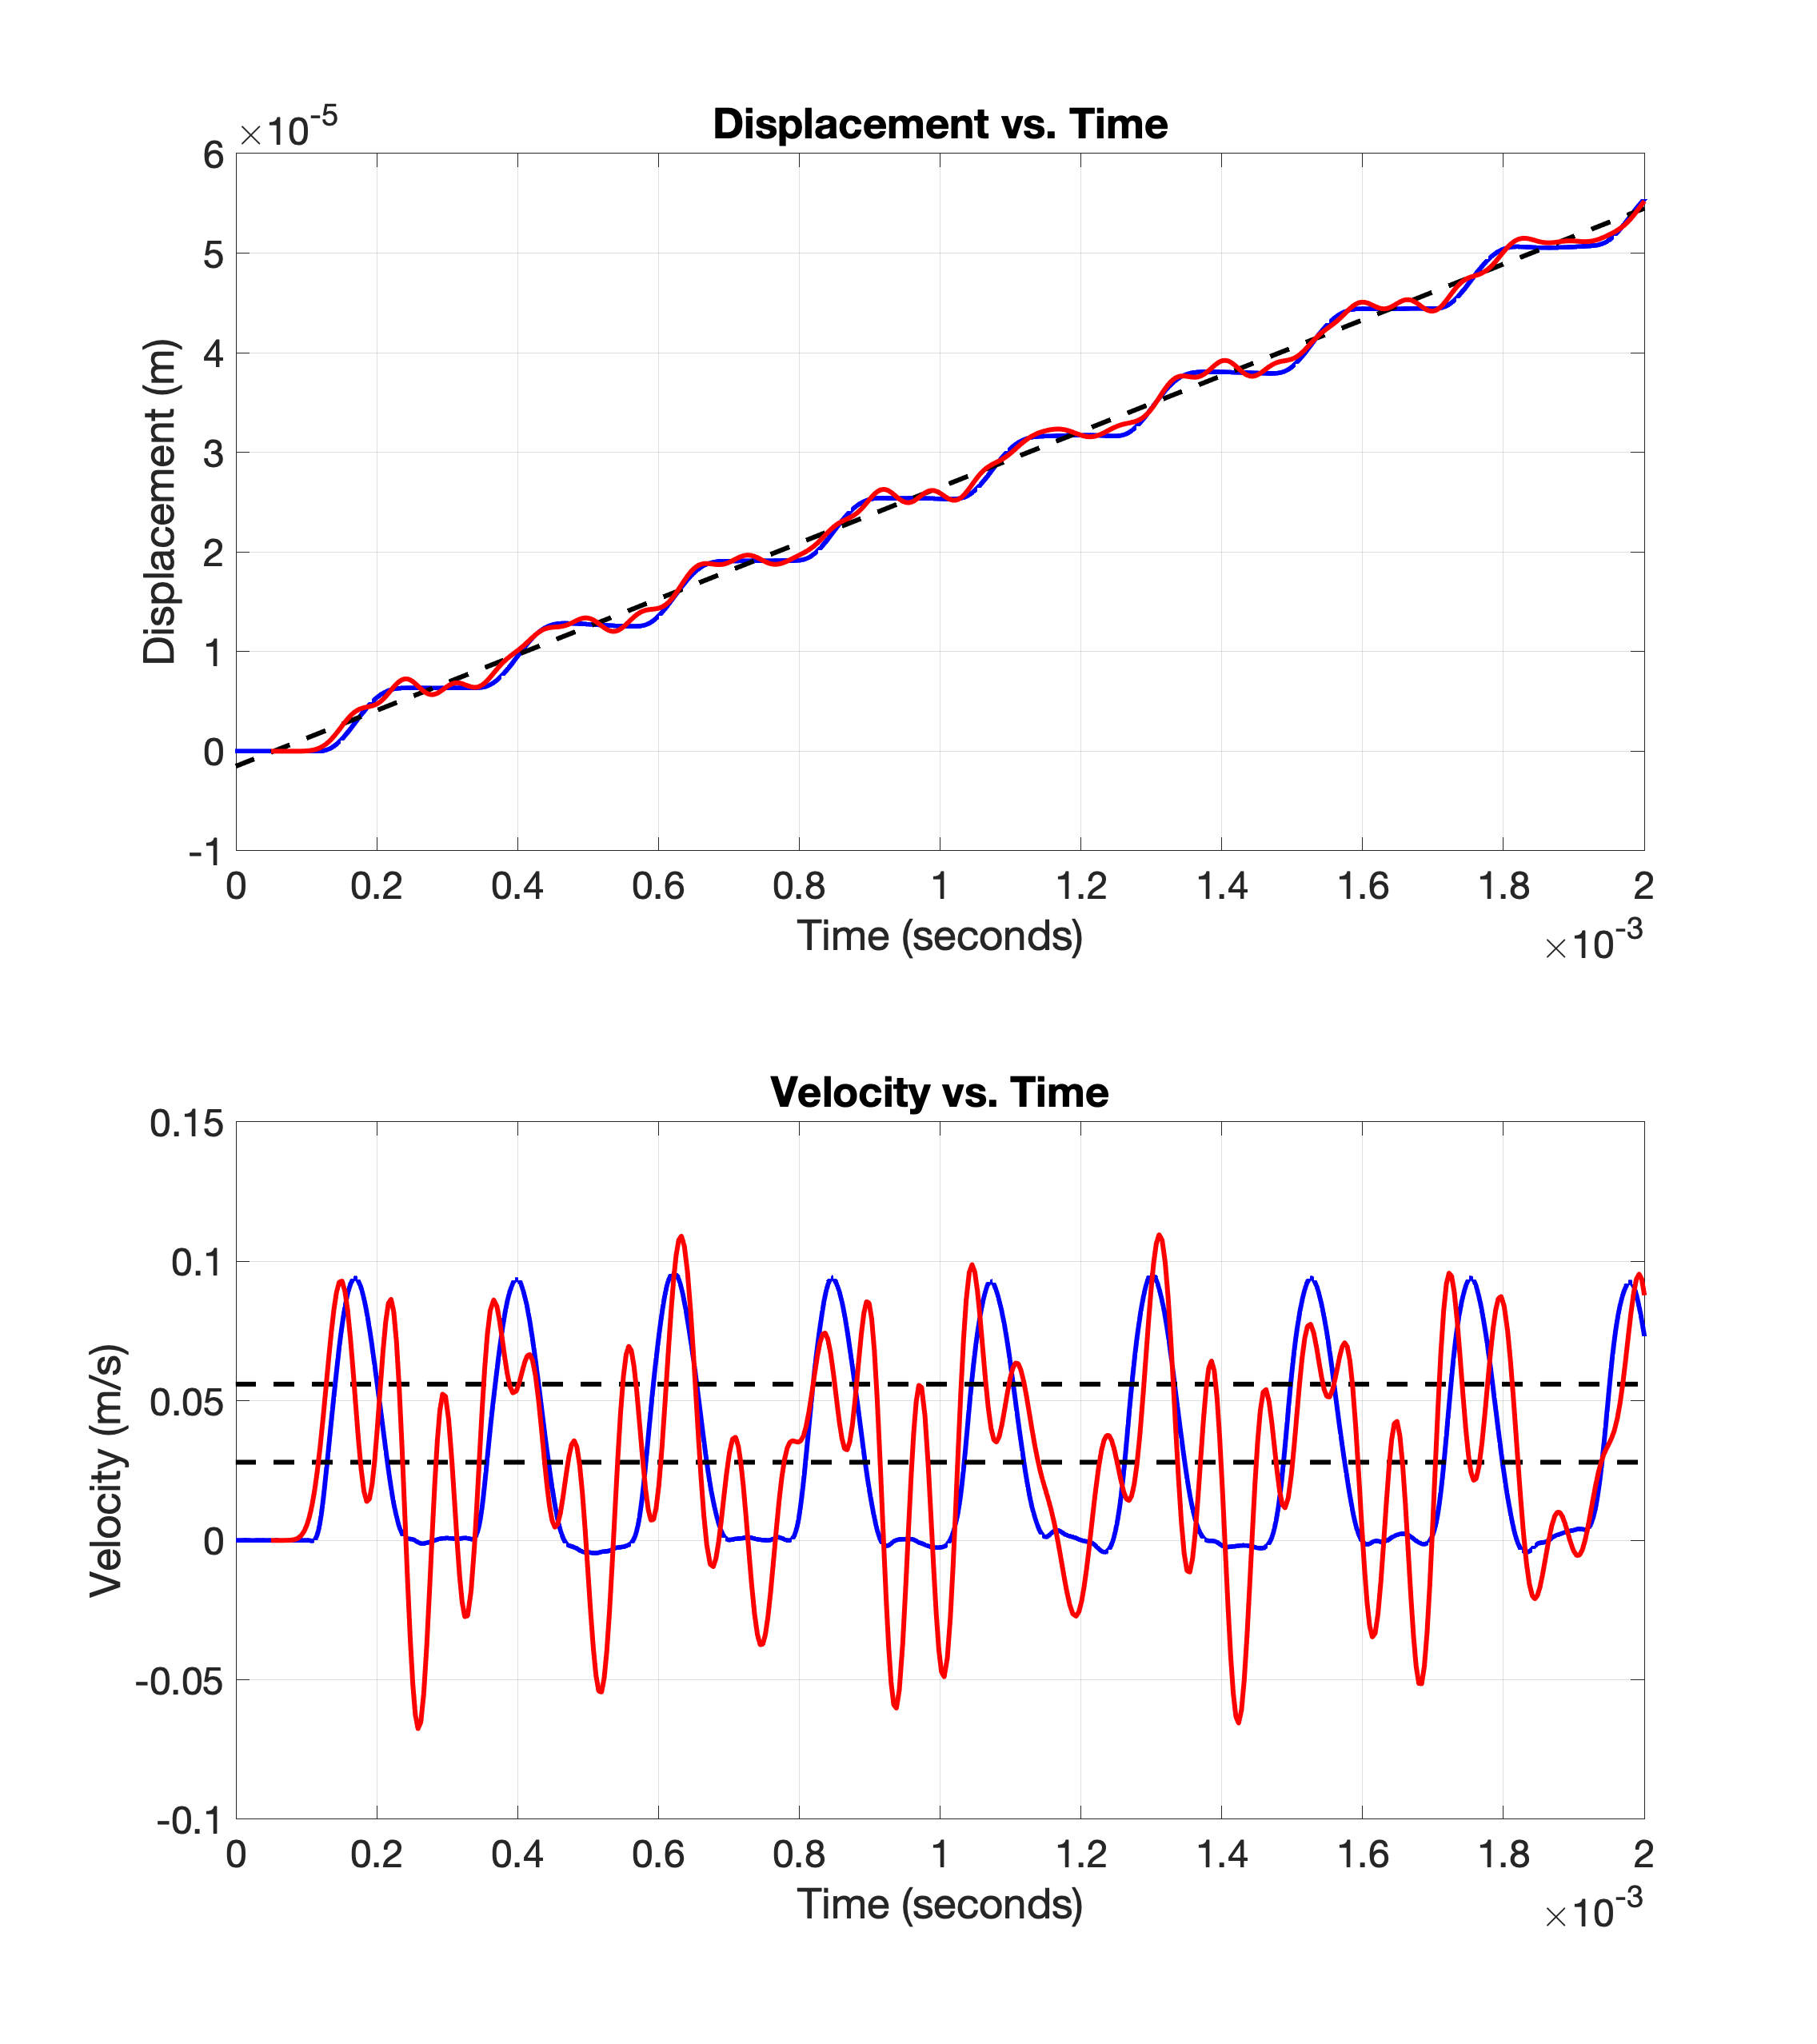

t_range = [0 0.002];
v_scale = 0.5*10^6;
offset = 0.05*10^-3;
% offset=0;

close all
figure(1)
subplot(2,1,1)
set(gcf,'units','normalized','position',[0 0 1 1.8]);
plot(t_ave_full(dt), du_ave_full(dt), 'LineWidth', 3, 'Color', 'b')
hold on
plot(t_ave_full(dt), y_cm,'--','LineWidth', 3 ,'Color', 'black')
plot(t_spr+offset, du_spr, 'LineWidth', 3,'Color', 'red')
hold off
title('Displacement vs. Time')
xlabel('Time (seconds)')
ylabel('Displacement (m)')
xlim(t_range) 
grid on
set(gca,'FontSize',font_size)


subplot(2,1,2)
plot(t_ave_full(dt), vel_ave_filt*v_scale, 'LineWidth', 3 ,'Color', 'b')
hold on
plot(t_ave_full(dt), y_v_cm,'--','LineWidth', 3 ,'Color', 'black')
plot(t_ave_full(dt), 2*y_v_cm,'--','LineWidth', 3 ,'Color', 'black')
plot(t_spr+offset, v_spr, 'LineWidth', 3,'Color', 'red')
hold off
title('Velocity vs. Time')
xlabel('Time (seconds)')
ylabel('Velocity (m/s)')
xlim(t_range) 
grid on
set(gca,'FontSize',font_size)